clear
close
load('rsdata.mat')

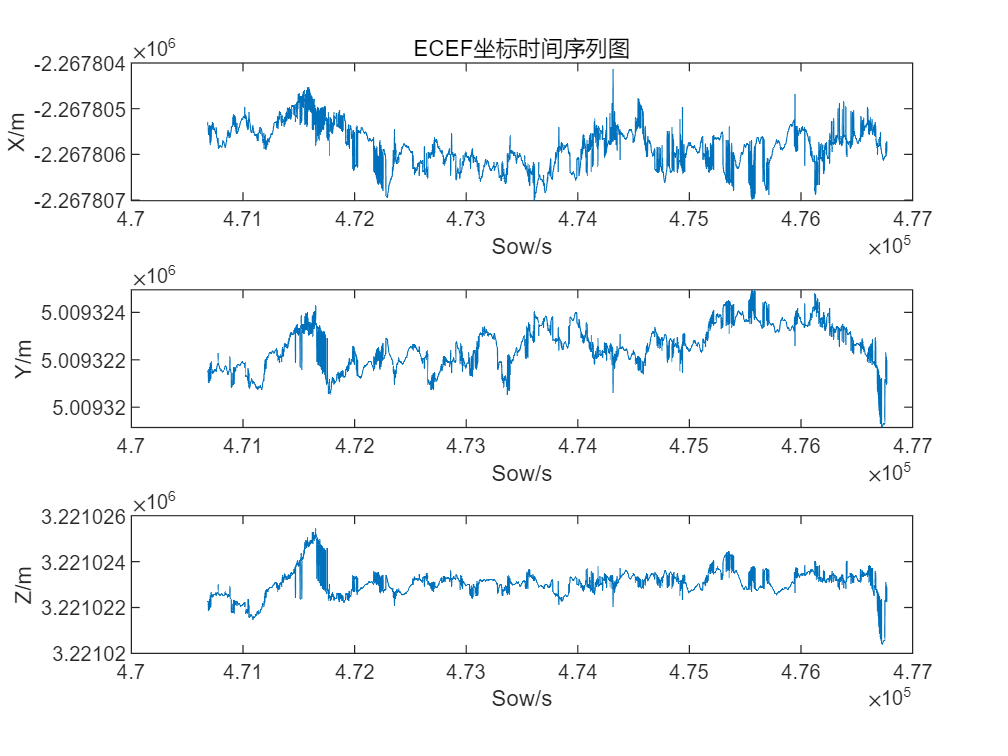

figure(1)
subplot(3,1,1)
plot(Sow,X)
subplot(3,1,2)
plot(Sow,Y)
subplot(3,1,3)
plot(Sow,Z)

subplot(3,1,1)
title("ECEF坐标时间序列图")
xlabel("Sow/s")
ylabel("X/m")
subplot(3,1,2)
xlabel("Sow/s")
ylabel("Y/m")
subplot(3,1,3)
xlabel("Sow/s")
ylabel("Z/m")

meanX=mean(X)

meanX = -2.2678e+06

meanY=mean(Y)

meanY = 5.0093e+06

meanZ=mean(Z)

meanZ = 3.2210e+06

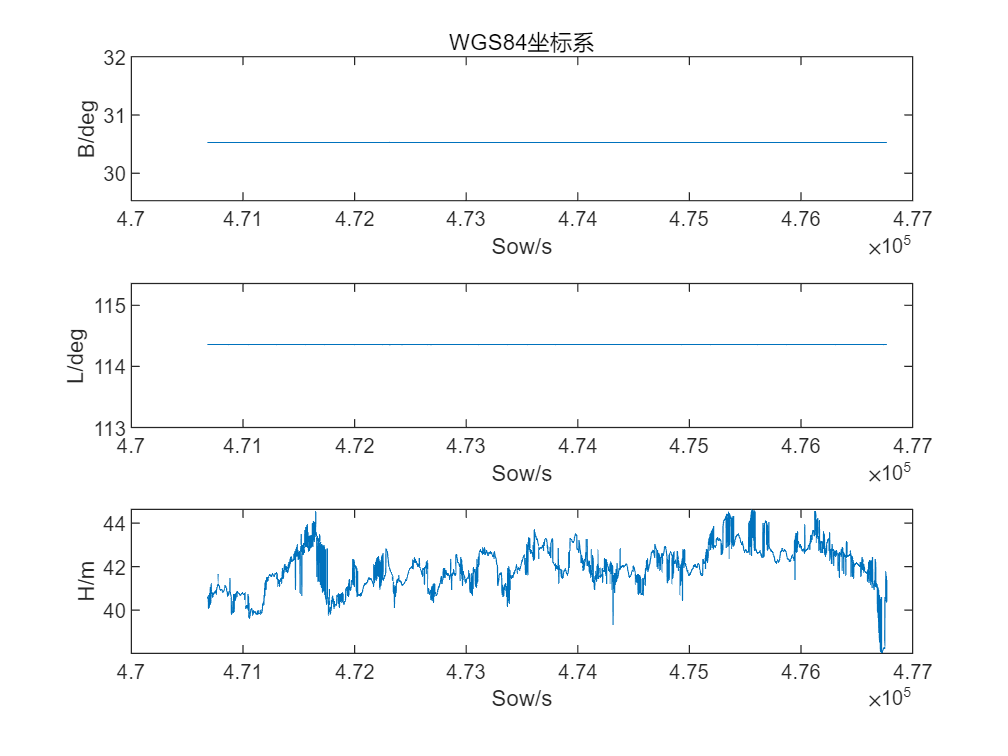

figure(2)
subplot(3,1,1)
plot(Sow,B)
subplot(3,1,2)
plot(Sow,L)
subplot(3,1,3)
plot(Sow,H)

subplot(3,1,1)
title("WGS84坐标系")
xlabel("Sow/s")
ylabel("B/deg")
subplot(3,1,2)
xlabel("Sow/s")
ylabel("L/deg")
subplot(3,1,3)
xlabel("Sow/s")
ylabel("H/m")

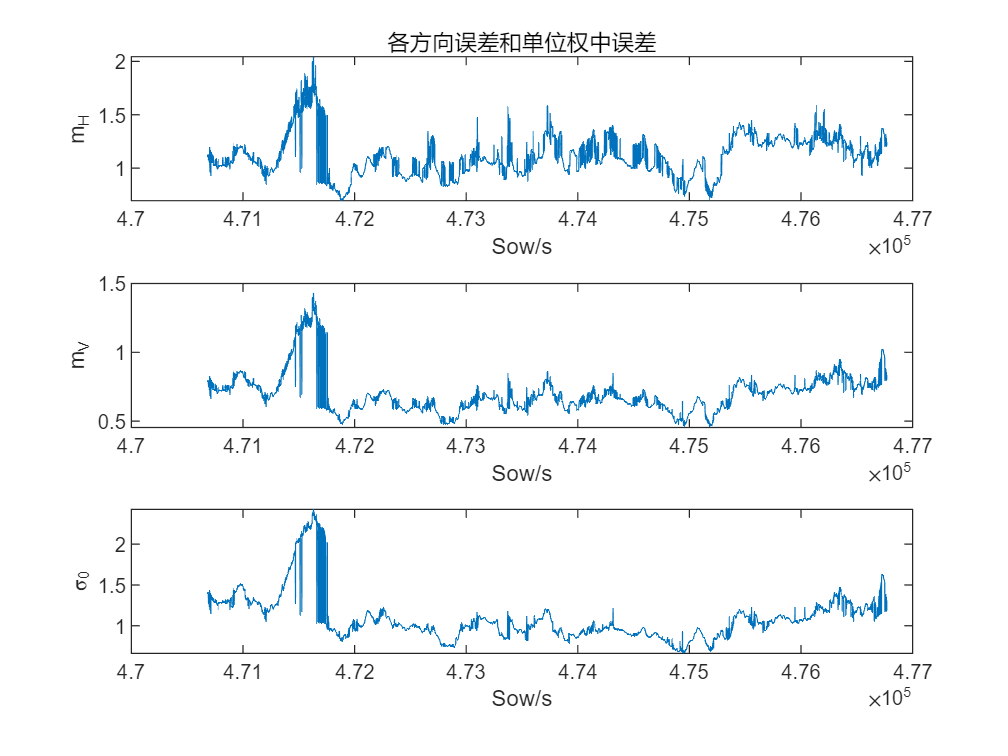

figure(3)
subplot(3,1,1)
plot(Sow,m_H)
subplot(3,1,2)
plot(Sow,m_V)
subplot(3,1,3)
plot(Sow,sigma0)

subplot(3,1,1)
title("各方向误差和单位权中误差")
xlabel("Sow/s")
ylabel("m_H")
subplot(3,1,2)
xlabel("Sow/s")
ylabel("m_V")
subplot(3,1,3)
xlabel("Sow/s")
ylabel("\sigma_0")

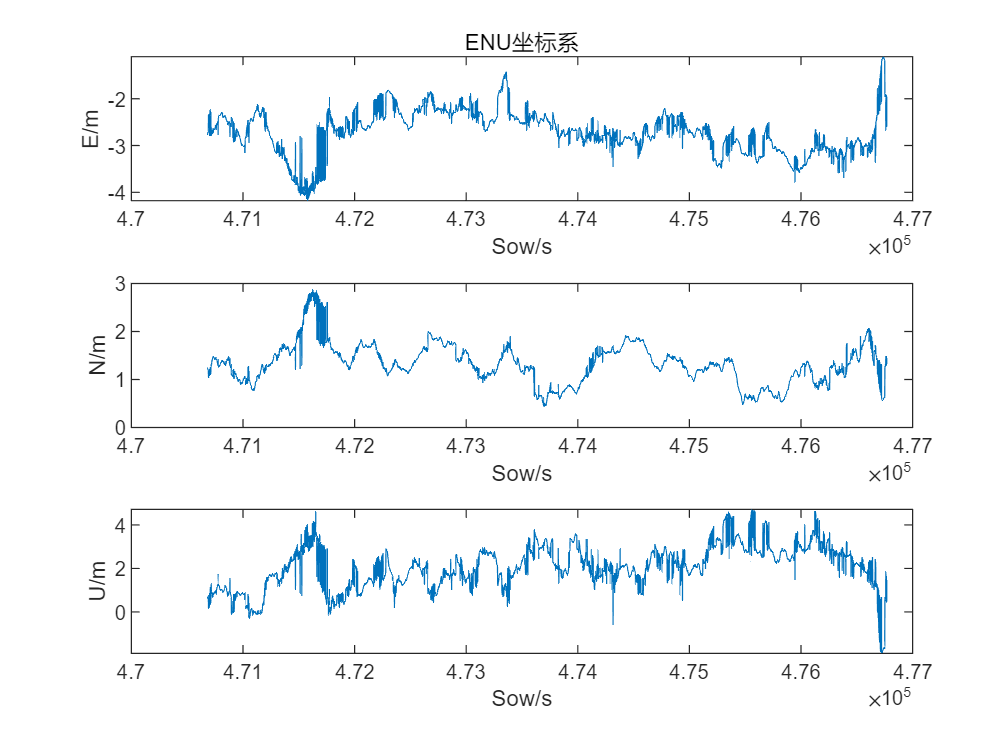

figure(4)
subplot(3,1,1)
plot(Sow,E)
subplot(3,1,2)
plot(Sow,N)
subplot(3,1,3)
plot(Sow,U)

subplot(3,1,1)
title("ENU坐标系")
xlabel("Sow/s")
ylabel("E/m")
subplot(3,1,2)
xlabel("Sow/s")
ylabel("N/m")
subplot(3,1,3)
xlabel("Sow/s")
ylabel("U/m")

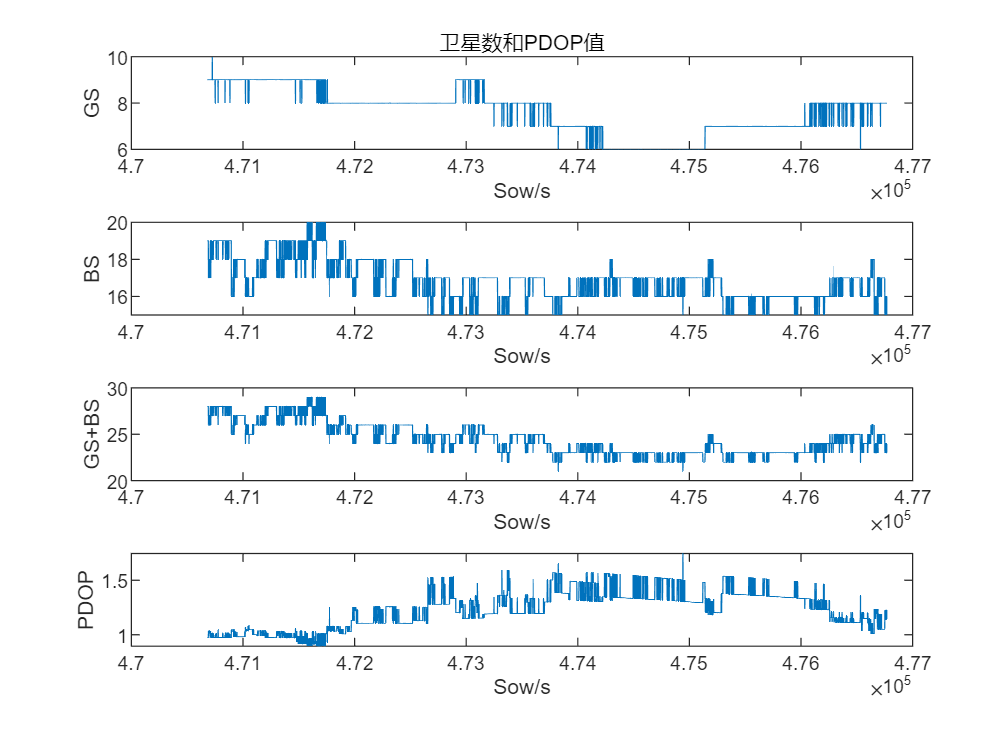

figure(5)
subplot(4,1,1)
plot(Sow,GS)
subplot(4,1,2)
plot(Sow,BS)
subplot(4,1,3)
plot(Sow,GS+BS)
subplot(4,1,4)
plot(Sow,PDOP)

subplot(4,1,1)
title("卫星数和PDOP值")
xlabel("Sow/s")
ylabel("GS")
subplot(4,1,2)
xlabel("Sow/s")
ylabel("BS")
subplot(4,1,3)
xlabel("Sow/s")
ylabel("GS+BS")
subplot(4,1,4)
xlabel("Sow/s")
ylabel("PDOP")

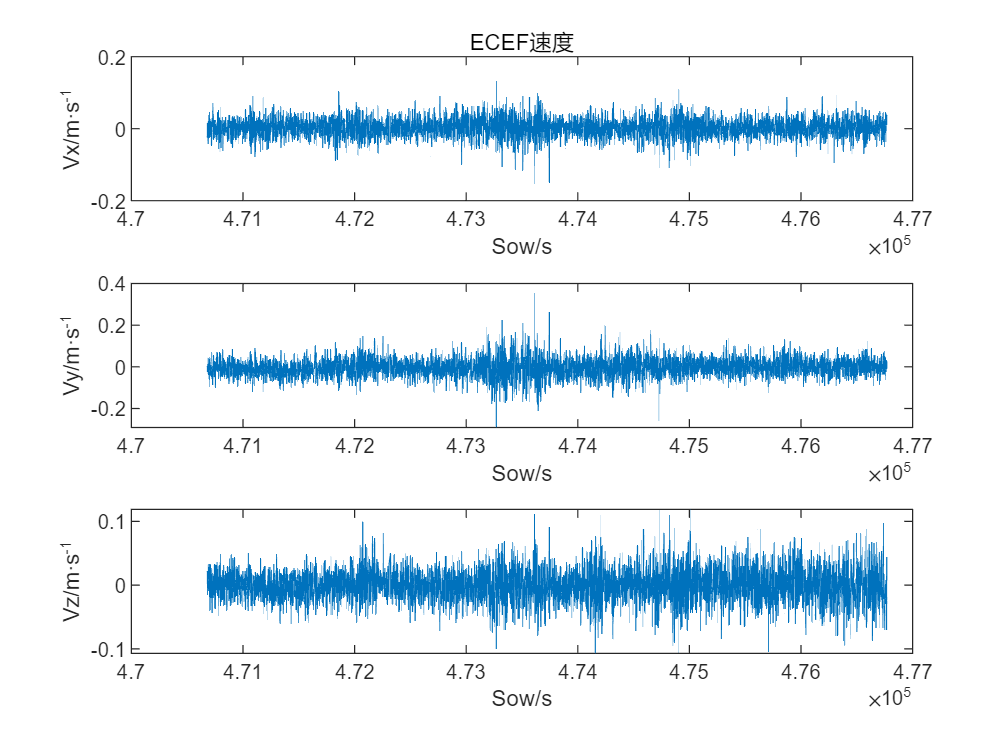

figure(6)
subplot(3,1,1)
plot(Sow,Vx)
subplot(3,1,2)
plot(Sow,Vy)
subplot(3,1,3)
plot(Sow,Vz)

subplot(3,1,1)
title("ECEF速度")
xlabel("Sow/s")
ylabel("Vx/m·s^{-1}")
subplot(3,1,2)
xlabel("Sow/s")
ylabel("Vy/m·s^{-1}")
subplot(3,1,3)
xlabel("Sow/s")
ylabel("Vz/m·s^{-1}")

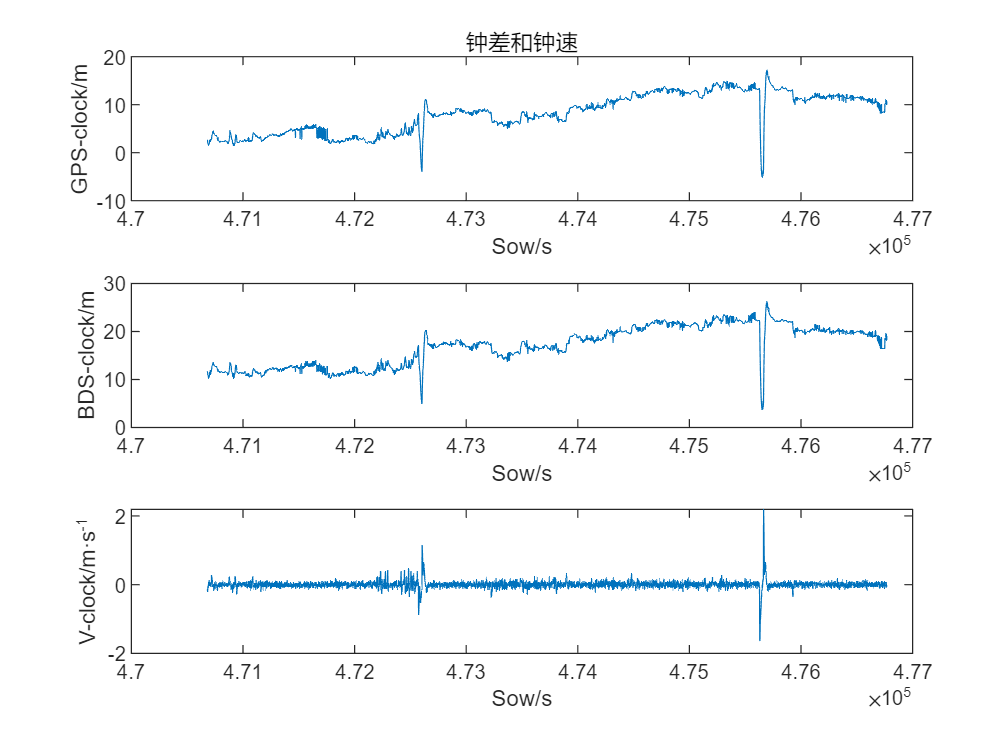

figure(7)
subplot(3,1,1)
plot(Sow,Gclock)
subplot(3,1,2)
plot(Sow,Cclock)
subplot(3,1,3)
plot(Sow,Vc)

subplot(3,1,1)
title("钟差和钟速")
xlabel("Sow/s")
ylabel("GPS-clock/m")
subplot(3,1,2)
xlabel("Sow/s")
ylabel("BDS-clock/m")
subplot(3,1,3)
xlabel("Sow/s")
ylabel("V-clock/m·s^{-1}")

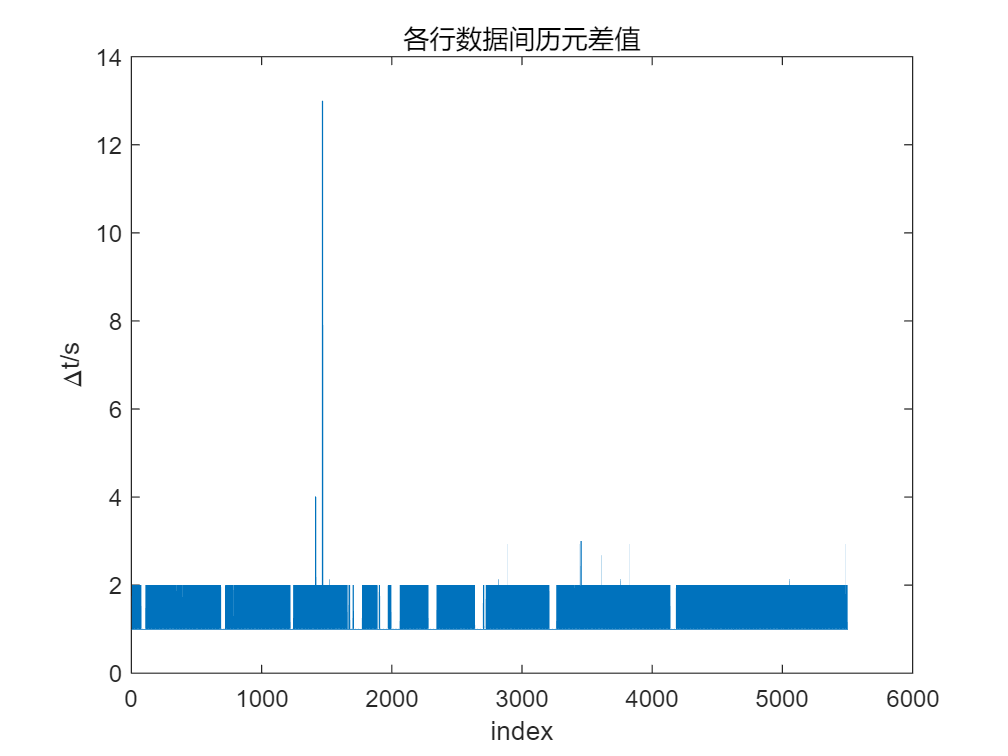

figure(8)
plot(Sow(2:end)-Sow(1:end-1))

title("各行数据间历元差值")
xlabel("index")
ylabel("{\Delta}t/s")

meanE=mean(E)

meanE = -2.7159

meanN=mean(N)

meanN = 1.3261

meanU=mean(U)

meanU = 2.0611

varE=var(E)

varE = 0.2292

varN=var(N)

varN = 0.1813

varU=var(U)

varU = 0.9918

figure(9)
scatter(E,N,3,U,'filled','DisplayName','E-N')
colormap('parula')
c=colorbar('Ticks',linspace(min(U),max(U),6))

c =   ColorBar - 属性:

    Location: 'eastoutside'
      Limits: [-1.9079 4.7155]
    FontSize: 9
    Position: [0.8315 0.1095 0.0381 0.8155]
       Units: 'normalized'

  显示 所有属性


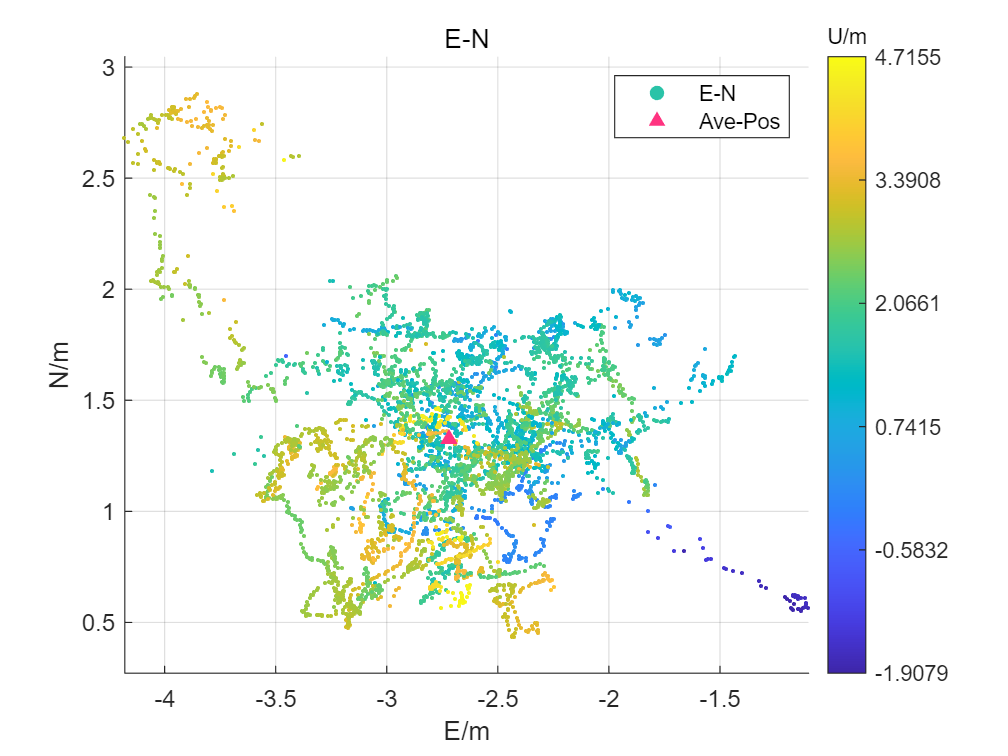

set(get(c,'Title'),'string','U/m');
title("E-N")
xlabel("E/m")
ylabel("N/m")
grid on
axis equal
hold on
% scatter(0,0,40,[1,0,0],'filled','DisplayName','Ref-Pos')
scatter(meanE,meanN,40,[1,0.2,0.5],'filled','^','DisplayName','Ave-Pos')
legend

[avx,taux]=Allan(Vx,1,2)

avx =     0.0251    0.0177    0.0126    0.0089    0.0063    0.0048    0.0032    0.0022    0.0015    0.0013    0.0013


taux =            1           2           4           8          16          32          64         128         256         512        1024


[avy,tauy]=Allan(Vy,1,2)

avy =     0.0440    0.0310    0.0219    0.0159    0.0113    0.0089    0.0064    0.0045    0.0042    0.0043    0.0034


tauy =            1           2           4           8          16          32          64         128         256         512        1024


[avz,tauz]=Allan(Vz,1,2)

avz =     0.0255    0.0179    0.0127    0.0089    0.0064    0.0047    0.0035    0.0028    0.0025    0.0020    0.0013


tauz =            1           2           4           8          16          32          64         128         256         512        1024


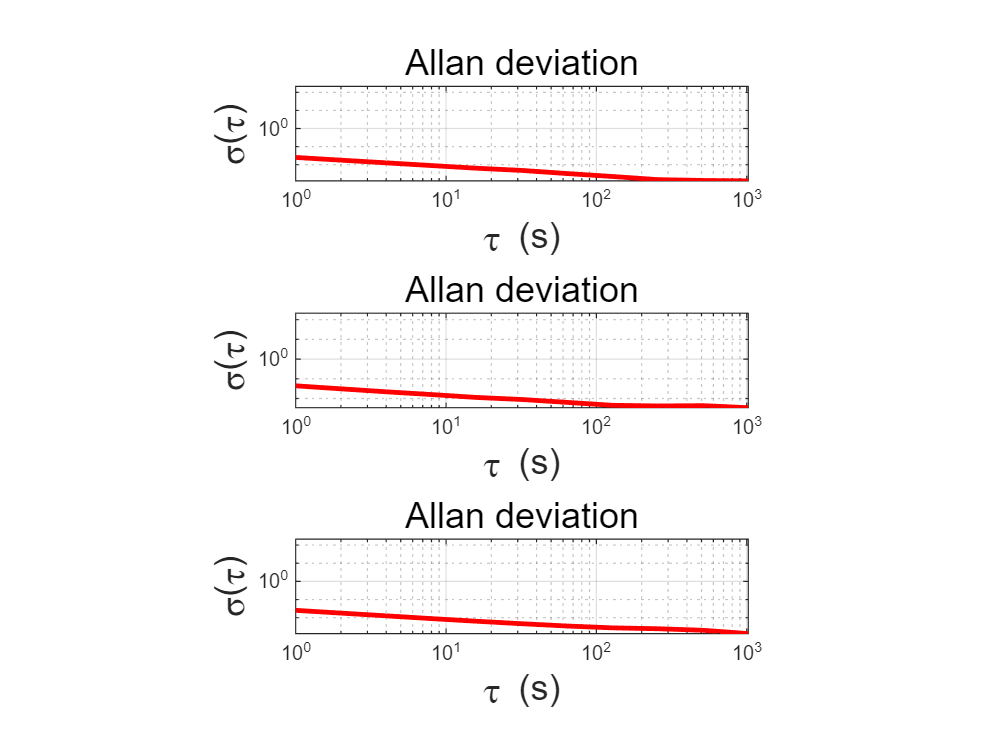

figure(10)
subplot(3,1,1)
AllanPlot(taux,avx)
subplot(3,1,2)
AllanPlot(tauy,avy)
subplot(3,1,3)
AllanPlot(tauz,avz)

[avs,taus]=Allan(sigma0,1,2)

avs =     0.0632    0.0466    0.0399    0.0368    0.0443    0.0638    0.0964    0.1489    0.1882    0.1626    0.1654


taus =            1           2           4           8          16          32          64         128         256         512        1024


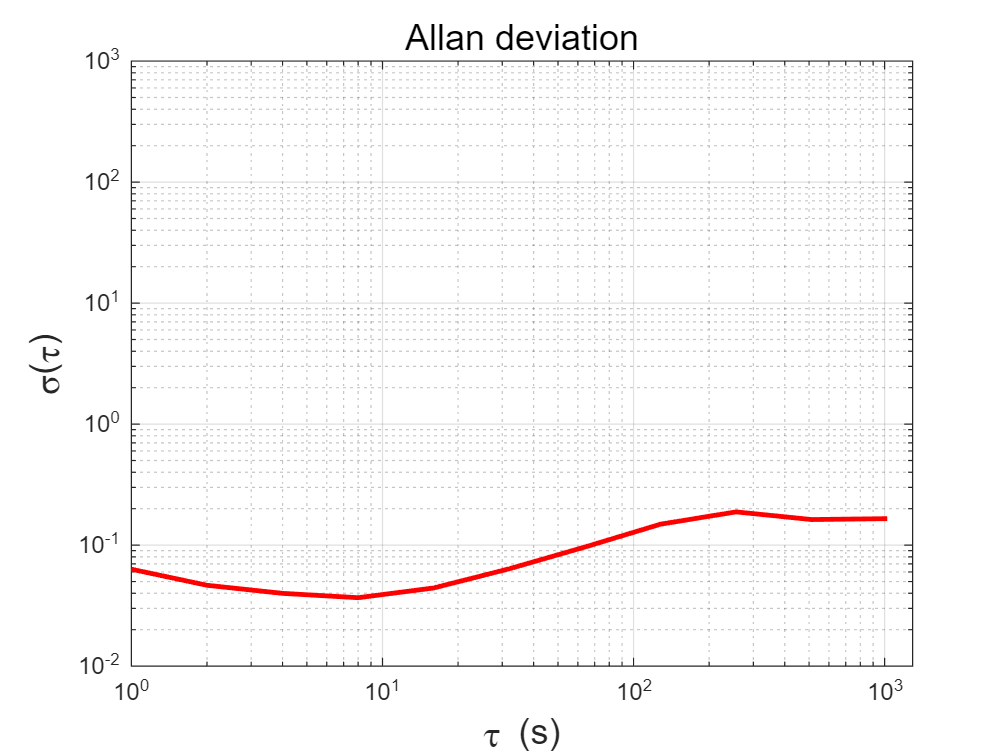

figure(11)
AllanPlot(taus,avs)

[avxx,tauxx]=Allan(X,1,2)

avxx =     0.1304    0.1022    0.0906    0.0984    0.1271    0.1590    0.1851    0.1999    0.2110    0.2537    0.2862


tauxx =            1           2           4           8          16          32          64         128         256         512        1024


[avyy,tauyy]=Allan(Y,1,2)

avyy =     0.1814    0.1428    0.1299    0.1518    0.2013    0.2632    0.3507    0.4274    0.4663    0.4177    0.4148


tauyy =            1           2           4           8          16          32          64         128         256         512        1024


[avzz,tauzz]=Allan(Z,1,2)

avzz =     0.1537    0.1189    0.1049    0.1137    0.1443    0.1901    0.2634    0.3364    0.3822    0.2842    0.1066


tauzz =            1           2           4           8          16          32          64         128         256         512        1024


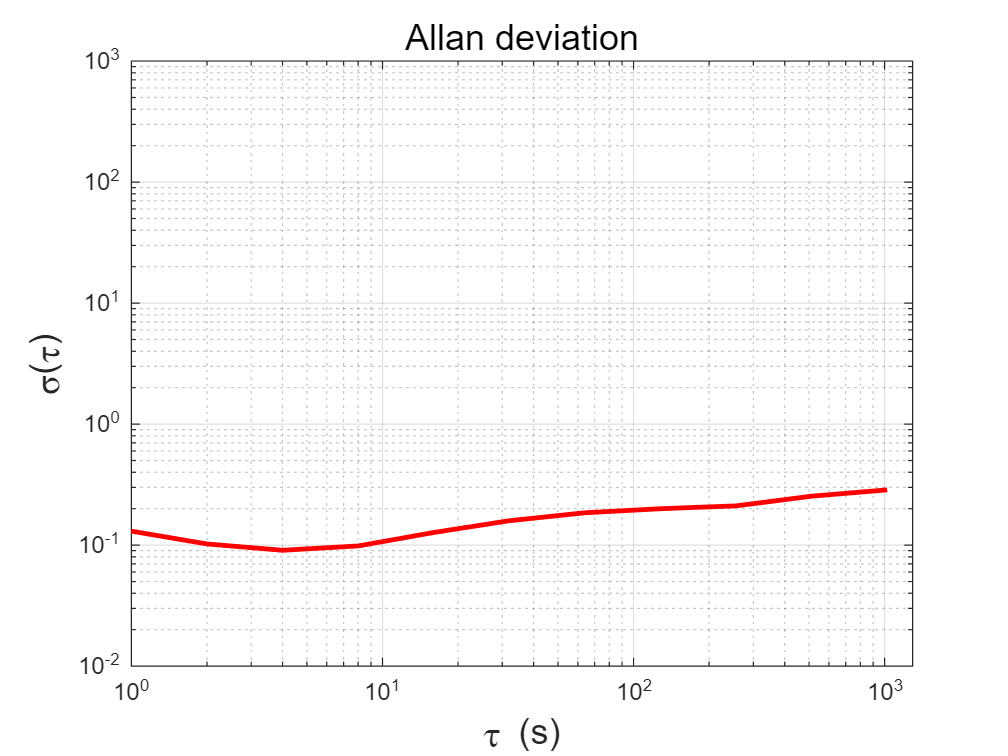

figure(12)
AllanPlot(tauxx,avxx)

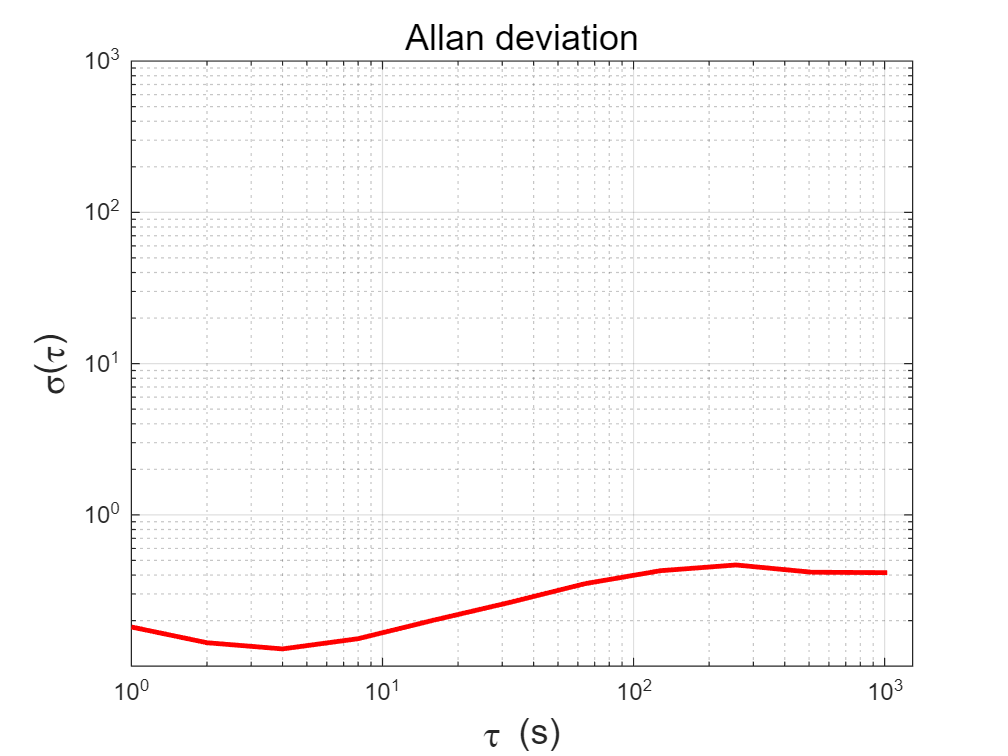

figure(13)
AllanPlot(tauyy,avyy)

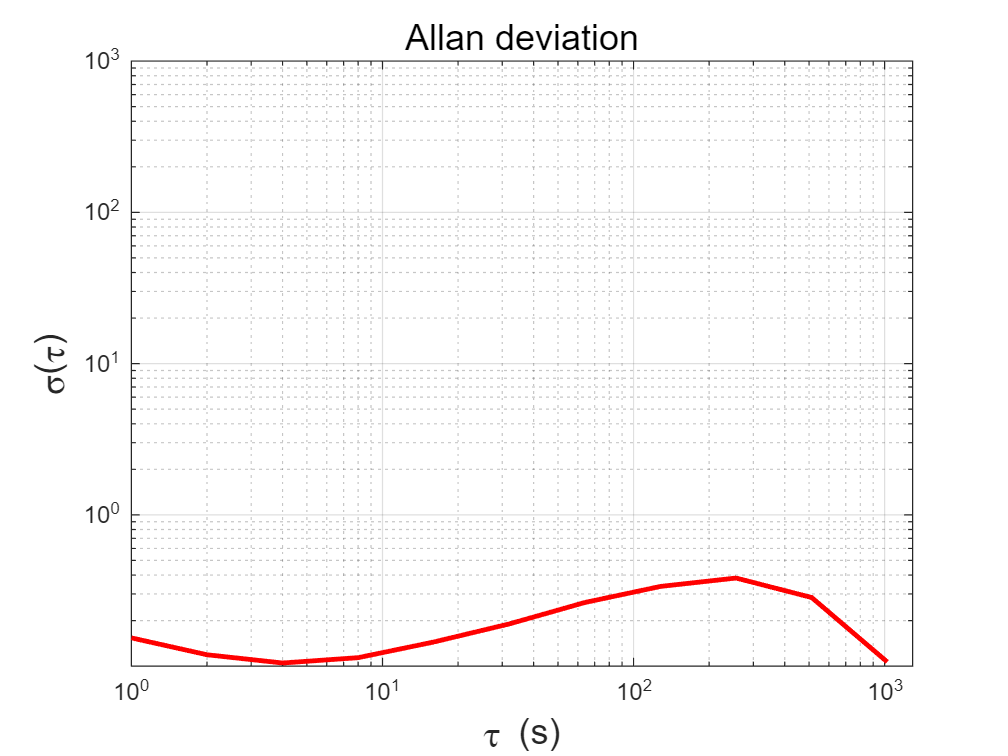

figure(14)
AllanPlot(tauzz,avzz)

figure(15)
scatter(E,N,3,sigma0,'filled','DisplayName','E-N')
colormap('turbo')
c=colorbar('Ticks',linspace(min(sigma0),max(sigma0),6))

c =   ColorBar - 属性:

    Location: 'eastoutside'
      Limits: [0.6617 2.4257]
    FontSize: 9
    Position: [0.8315 0.1095 0.0381 0.8155]
       Units: 'normalized'

  显示 所有属性


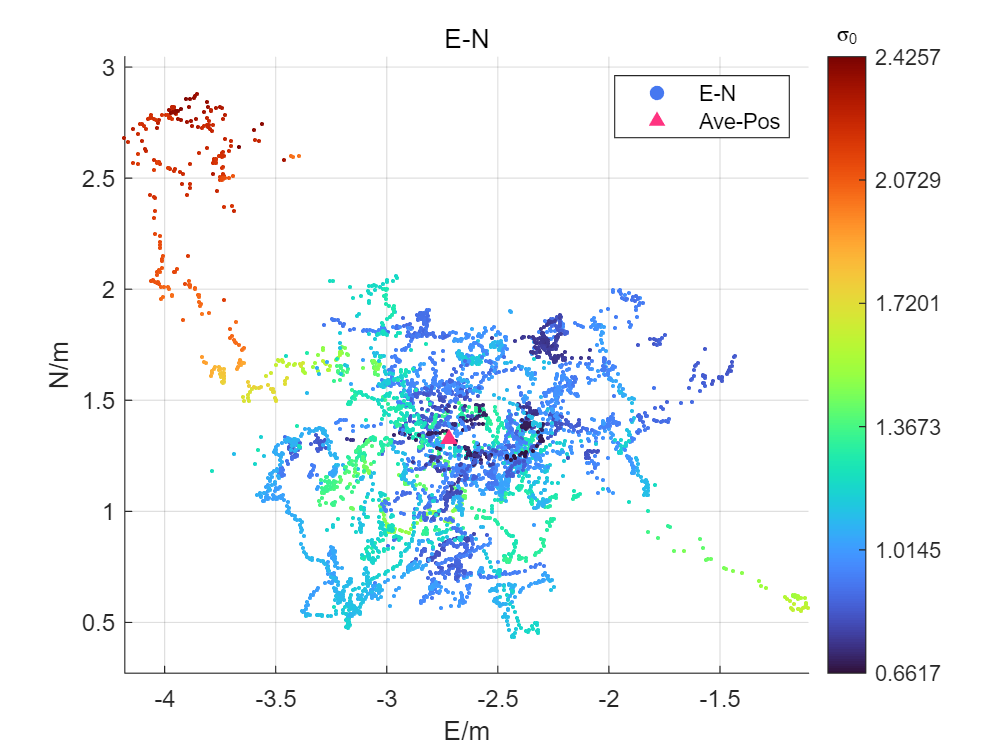

set(get(c,'Title'),'string','\sigma_0');
title("E-N")
xlabel("E/m")
ylabel("N/m")
grid on
axis equal
hold on
% scatter(0,0,40,[1,0,0],'filled','DisplayName','Ref-Pos')
scatter(meanE,meanN,40,[1,0.2,0.5],'filled','^','DisplayName','Ave-Pos')
legend